## Marker-Controlled Watershed Segmentation 

The watershed transform finds "catchment basins" and "watershed ridge lines" in an image by treating it as a surface where light pixels are high and dark pixels are low.

Segmentation using the watershed transform works better if you can identify, or "mark," foreground objects and background locations. Marker-controlled watershed segmentation follows this basic procedure:

1. Compute a segmentation function. This is an image whose dark regions are the objects you are trying to segment.

2. Compute foreground markers. These are connected blobs of pixels within each of the objects.

3. Compute background markers. These are pixels that are not part of any object.

4. Modify the segmentation function so that it only has minima at the foreground and background marker locations.

5. Compute the watershed transform of the modified segmentation function.

This example highlights many different Image Processing Toolbox™ functions, including `imgradient`, `watershed`, `label2rgb`, `labeloverlay`, `imopen`, `imclose`, `imreconstruct`, `imcomplement`, `imregionalmax`, `bwareaopen`, `graythresh`, and `imimposemin`.

**Step 1: Read in the Color Image and Convert it to Grayscale**

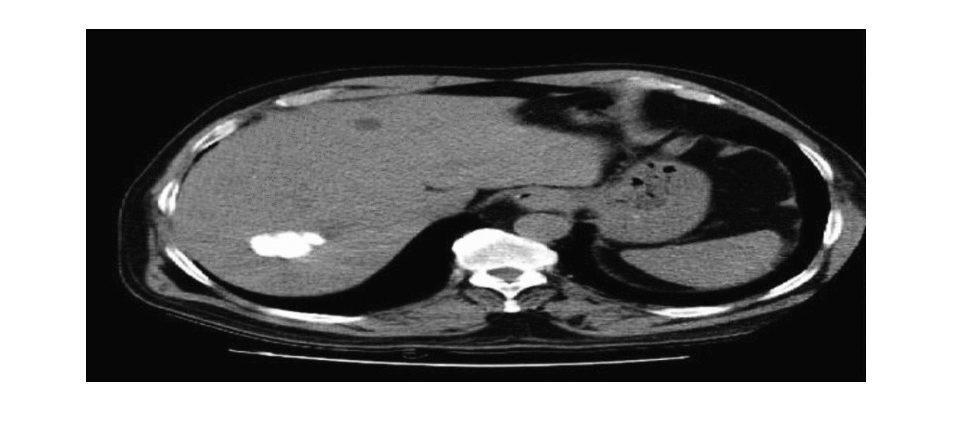

rgb = imread('E:\matlab_code\original.jpg');
I = rgb2gray(rgb);
imshow(I)

**Step 2: Use the Gradient Magnitude as the Segmentation Function**

Compute the gradient magnitude. The gradient is high at the borders of the objects and low (mostly) inside the objects.

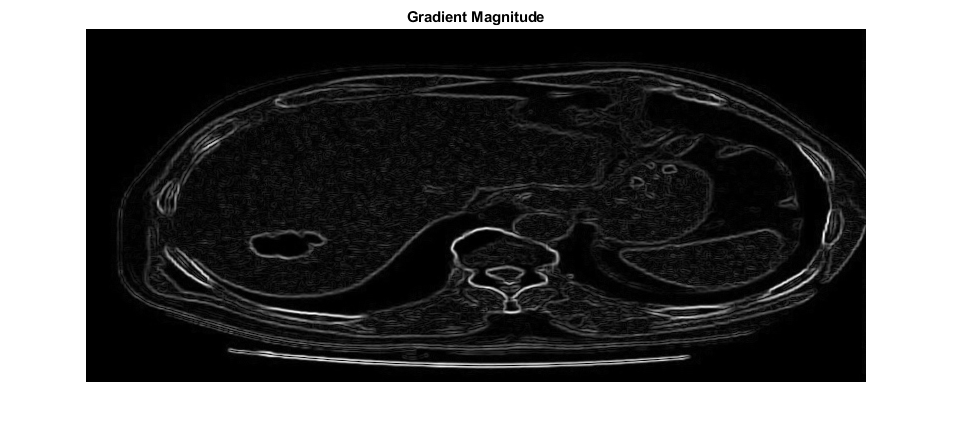

gmag = imgradient(I);
imshow(gmag,[])
title('Gradient Magnitude')

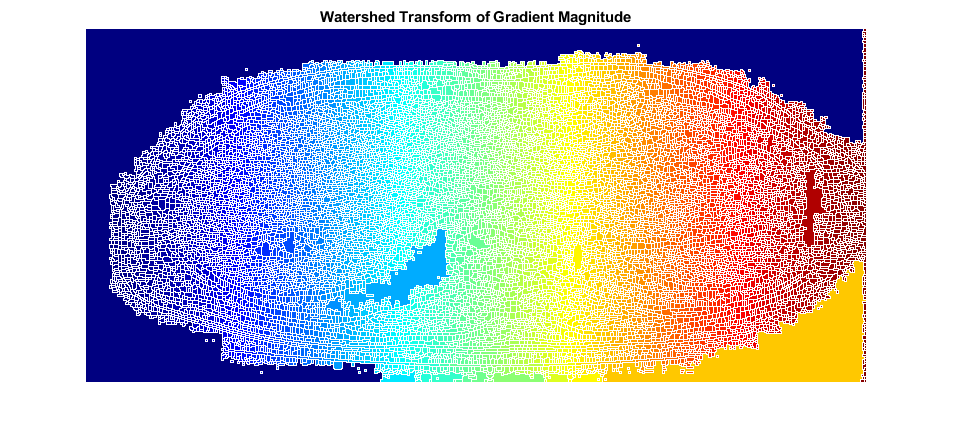



L = watershed(gmag);
Lrgb = label2rgb(L);
imshow(Lrgb)
title('Watershed Transform of Gradient Magnitude')

**Step 3: Mark the Foreground Objects**

A variety of procedures could be applied here to find the foreground markers, which must be connected blobs of pixels inside each of the foreground objects. In this example you'll use morphological techniques called "opening-by-reconstruction" and "closing-by-reconstruction" to "clean" up the image. These operations will create flat maxima inside each object that can be located using `imregionalmax`.

Opening is an erosion followed by a dilation, while opening-by-reconstruction is an erosion followed by a morphological reconstruction. Let's compare the two. First, compute the opening using `imopen`.

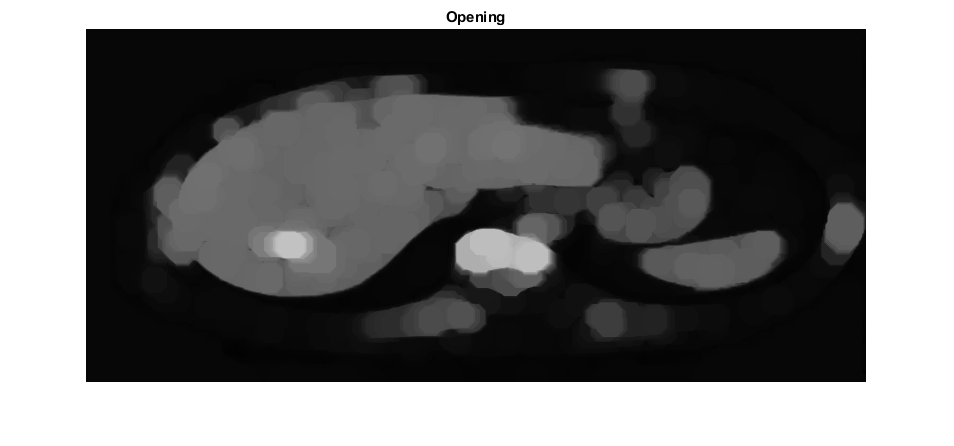

se = strel('disk',13);

Io = imopen(I,se);
imshow(Io)
title('Opening')

Next compute the opening-by-reconstruction using `imerode` and `imreconstruct`.

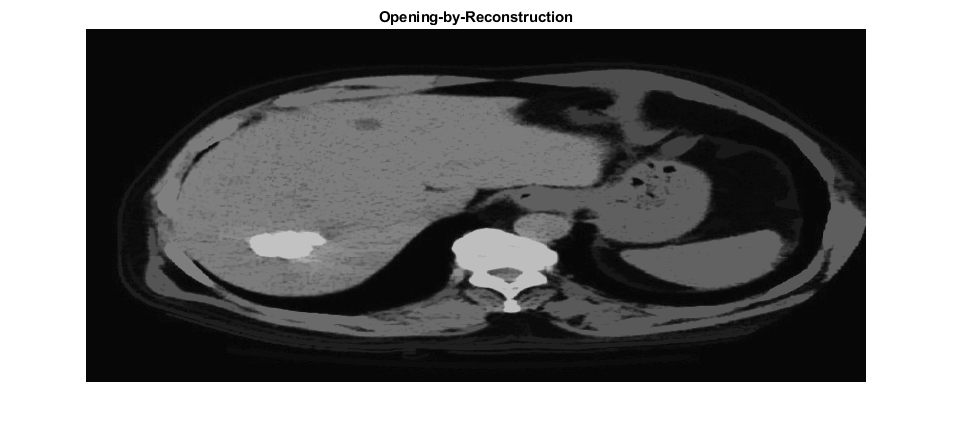

Ie = imerode(I,se);
Iobr = imreconstruct(Ie,I);
imshow(Iobr)
title('Opening-by-Reconstruction')

Following the opening with a closing can remove the dark spots and stem marks. Compare a regular morphological closing with a closing-by-reconstruction. First try `imclose`:

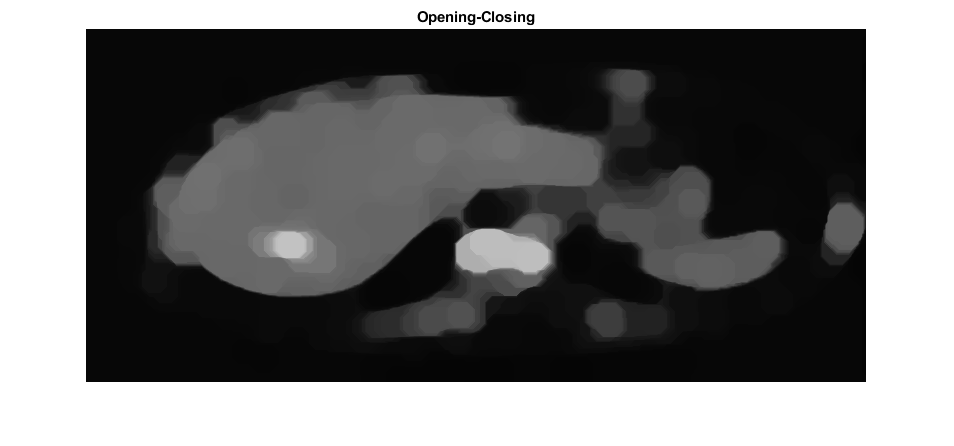

Ioc = imclose(Io,se);
imshow(Ioc)
title('Opening-Closing')

Now use `imdilate` followed by `imreconstruct`. Notice you must complement the image inputs and output of `imreconstruct`.

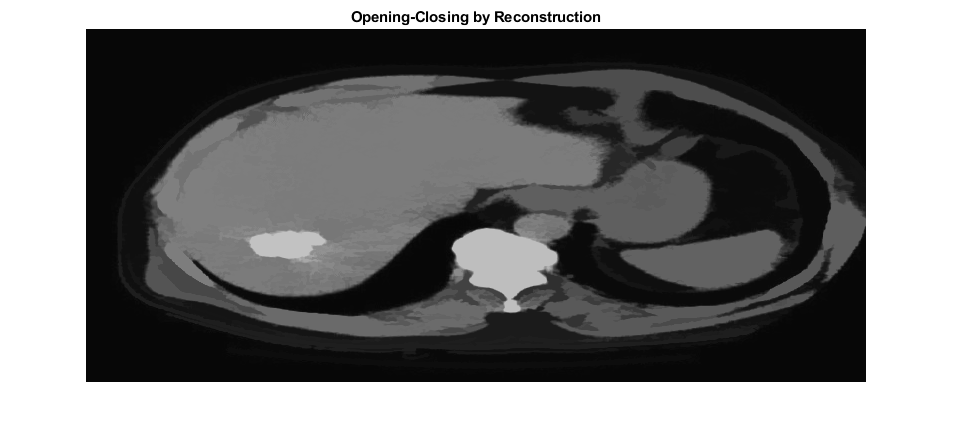

Iobrd = imdilate(Iobr,se);
Iobrcbr = imreconstruct(imcomplement(Iobrd),imcomplement(Iobr));
Iobrcbr = imcomplement(Iobrcbr);
imshow(Iobrcbr)
title('Opening-Closing by Reconstruction')

As you can see by comparing `Iobrcbr` with `Ioc`, reconstruction-based opening and closing are more effective than standard opening and closing at removing small blemishes without affecting the overall shapes of the objects. Calculate the regional maxima of `Iobrcbr` to obtain good foreground markers.

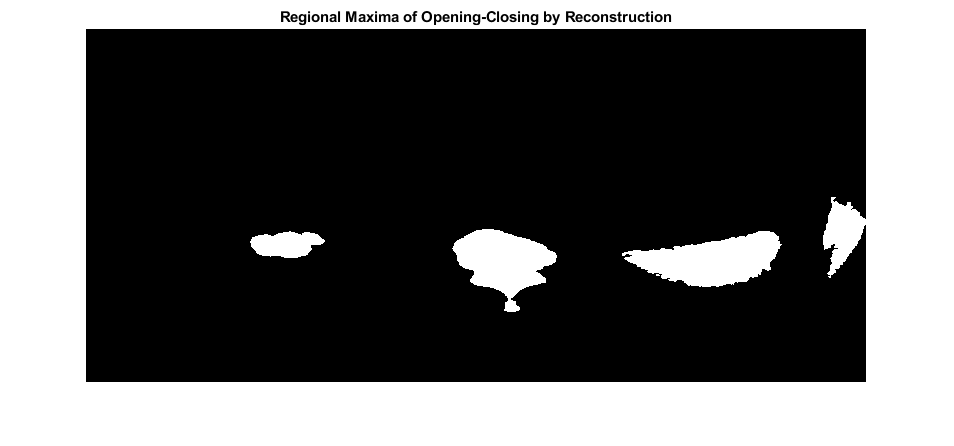

fgm = imregionalmax(Iobrcbr);
imshow(fgm)
title('Regional Maxima of Opening-Closing by Reconstruction')

To help interpret the result, superimpose the foreground marker image on the original image.

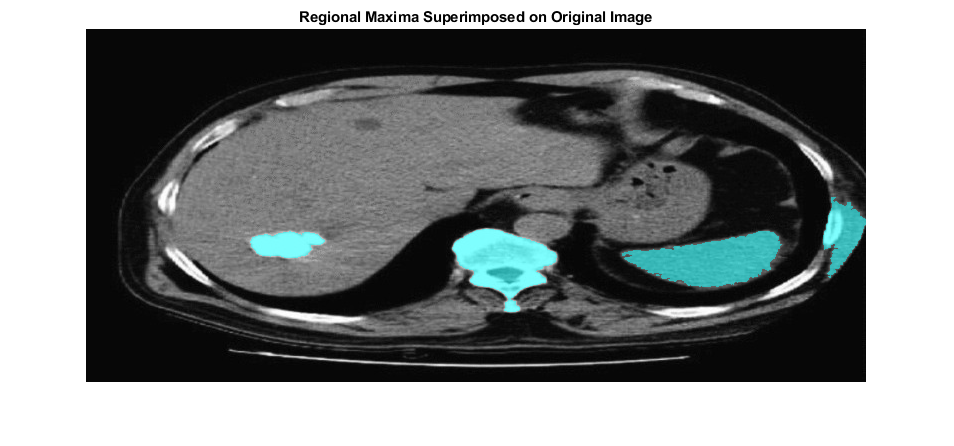

I2 = labeloverlay(I,fgm);
imshow(I2)
title('Regional Maxima Superimposed on Original Image')

Notice that some of the mostly-occluded and shadowed objects are not marked, which means that these objects will not be segmented properly in the end result. Also, the foreground markers in some objects go right up to the objects' edge. That means you should clean the edges of the marker blobs and then shrink them a bit. You can do this by a closing followed by an erosion.

se2 = strel(ones(5,5));
fgm2 = imclose(fgm,se2);
fgm3 = imerode(fgm2,se2);

This procedure tends to leave some stray isolated pixels that must be removed. You can do this using `bwareaopen`, which removes all blobs that have fewer than a certain number of pixels.

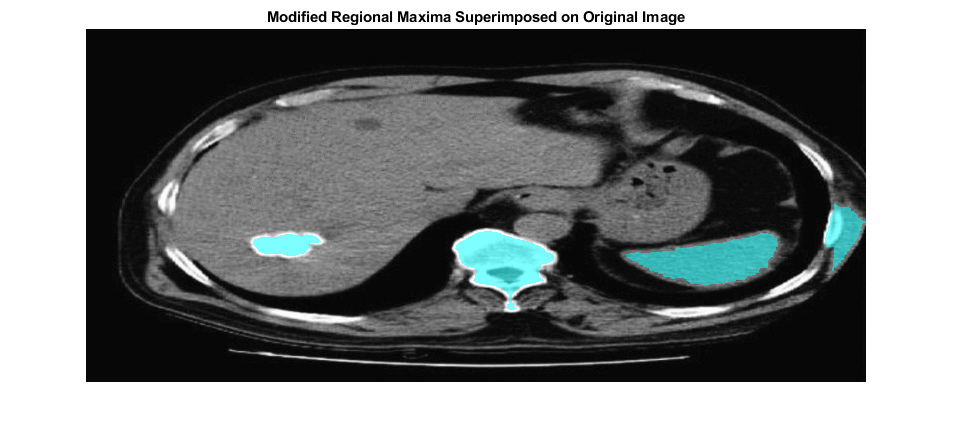

fgm4 = bwareaopen(fgm3,20);
I3 = labeloverlay(I,fgm4);
imshow(I3)
title('Modified Regional Maxima Superimposed on Original Image')

**Step 4: Compute Background Markers**

Now you need to mark the background. In the cleaned-up image, `Iobrcbr`, the dark pixels belong to the background, so you could start with a thresholding operation.

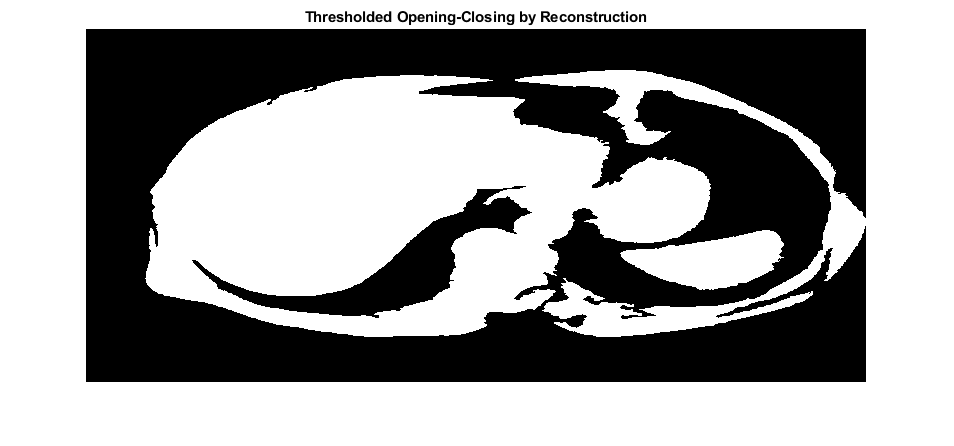

bw = imbinarize(Iobrcbr);
imshow(bw)
title('Thresholded Opening-Closing by Reconstruction')

The background pixels are in black, but ideally we don't want the background markers to be too close to the edges of the objects we are trying to segment. We'll "thin" the background by computing the "skeleton by influence zones", or SKIZ, of the foreground of `bw`. This can be done by computing the watershed transform of the distance transform of `bw`, and then looking for the watershed ridge lines (`DL == 0`) of the result.

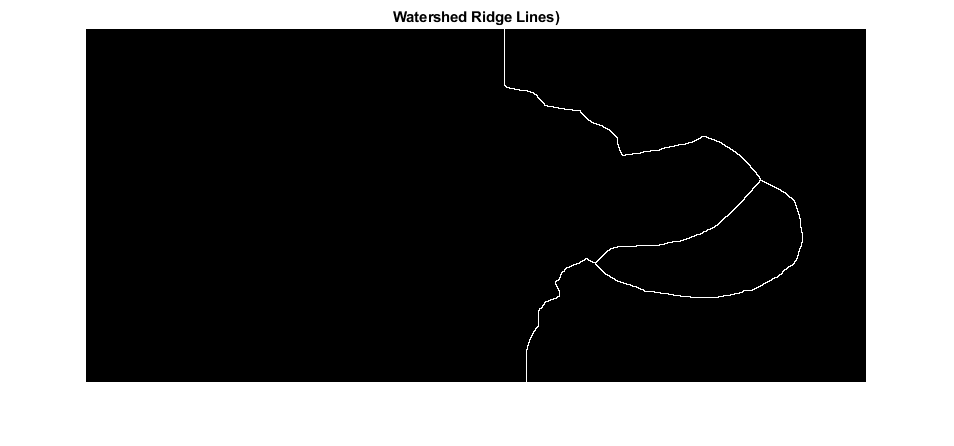

D = bwdist(bw);
DL = watershed(D);
bgm = DL == 0;
imshow(bgm)
title('Watershed Ridge Lines)')

**Step 5: Compute the Watershed Transform of the Segmentation Function.**

The function `imimposemin` can be used to modify an image so that it has regional minima only in certain desired locations. Here you can use `imimposemin` to modify the gradient magnitude image so that its only regional minima occur at foreground and background marker pixels.

gmag2 = imimposemin(gmag, bgm | fgm4);

Finally we are ready to compute the watershed-based segmentation.

L = watershed(gmag2);


**Step 6: Visualize the Result**

One visualization technique is to superimpose the foreground markers, background markers, and segmented object boundaries on the original image. You can use dilation as needed to make certain aspects, such as the object boundaries, more visible. Object boundaries are located where `L == 0`. The binary foreground and background markers are scaled to different integer values so that they are assigned different labels.

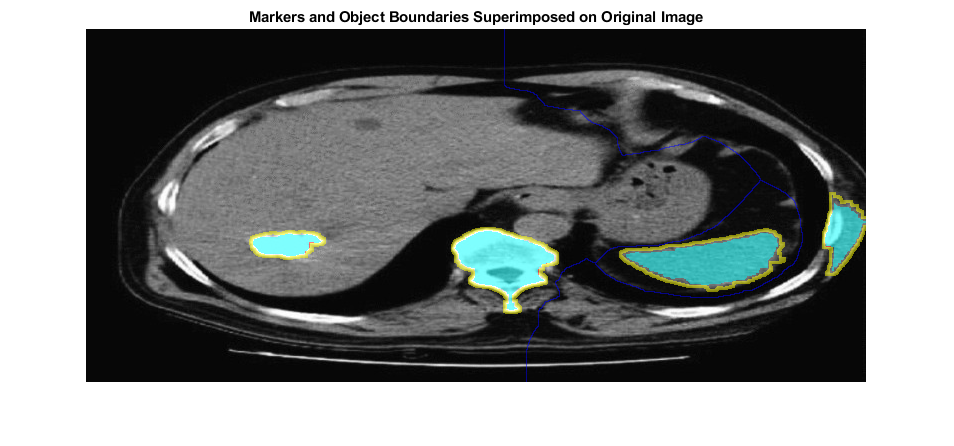


labels = imdilate(L==0,ones(3,3)) + 2*bgm + 3*fgm4;
I4 = labeloverlay(I,labels);
imshow(I4)
title('Markers and Object Boundaries Superimposed on Original Image')

This visualization illustrates how the locations of the foreground and background markers affect the result. In a couple of locations, partially occluded darker objects were merged with their brighter neighbor objects because the occluded objects did not have foreground markers.

Another useful visualization technique is to display the label matrix as a color image. Label matrices, such as those produced by `watershed` and `bwlabel`, can be converted to truecolor images for visualization purposes by using `label2rgb`.

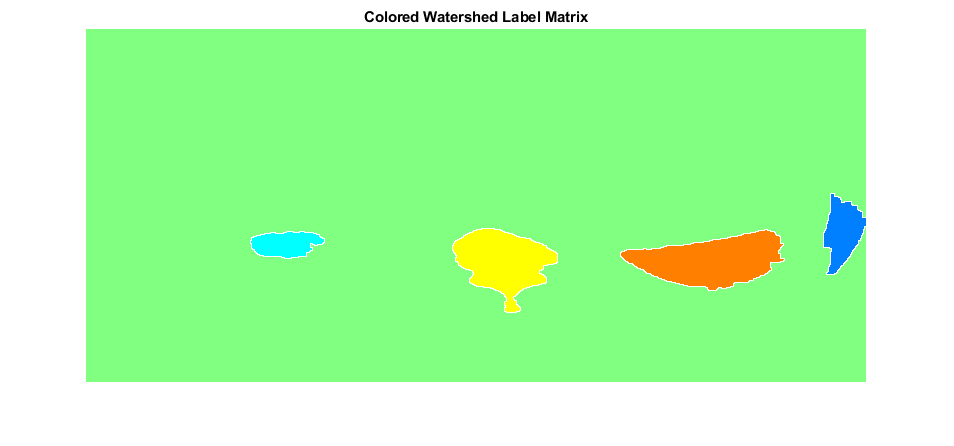

Lrgb = label2rgb(L,'jet','w','shuffle');
imshow(Lrgb)
title('Colored Watershed Label Matrix')

You can use transparency to superimpose this pseudo-color label matrix on top of the original intensity image.

figure
imshow(I)
hold on
himage = imshow(Lrgb);
himage.AlphaData = 0.3;
title('Colored Labels Superimposed Transparently on Original Image')


Geometrical features

folder = 'E:\matlab_code';
fullFileName = fullfile(folder,'I2.jpg');
imwrite(fgm, fullFileName);
img1=imread('E:\matlab_code\I2.jpg');
imshow(img1)

%img1=rgb2gray(img1);
%imshow(img1)

img2=imbinarize(img1,graythresh(img1));
imshow(img2)
number_of_white_pixels = nnz(img2);
disp(number_of_white_pixels)

       13382



bwarea(img2)

ans = 1.3430e+04

img3=~img2;
imshow(img3)

B = bwboundaries(img3);
imshow(img3)
text(10,10,strcat('\color{green}Objects Found:',num2str(length(B))))
hold on

for k = 1:length(B)
boundary = B{k};
plot(boundary(:,2), boundary(:,1), 'g', 'LineWidth', 0.2)
end
disp("The no of object are :")

The no of object are :


disp(length(B))

     5



format long
i=imread('E:\matlab_code\I2.jpg');
imshow(i);
bw=edge(i,'canny');
imshow(bw);
bw = bwareaopen(bw,30);
se = strel('disk',2);
bw = imclose(bw,se);
bw = imfill(bw,'holes');
imshow(bw);
L = bwlabel(bw);
s  = regionprops(L, 'centroid');
dt  = regionprops(L, 'area');
cv = regionprops(L, 'perimeter');
dim = size(s)

dim =      4     1


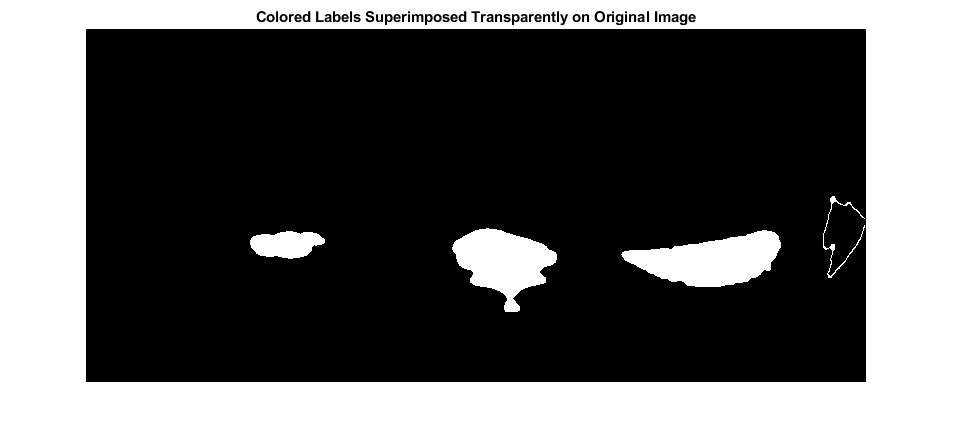

BW_filled = imfill(bw,'holes');
boundaries = bwboundaries(BW_filled);
imshow(bw);

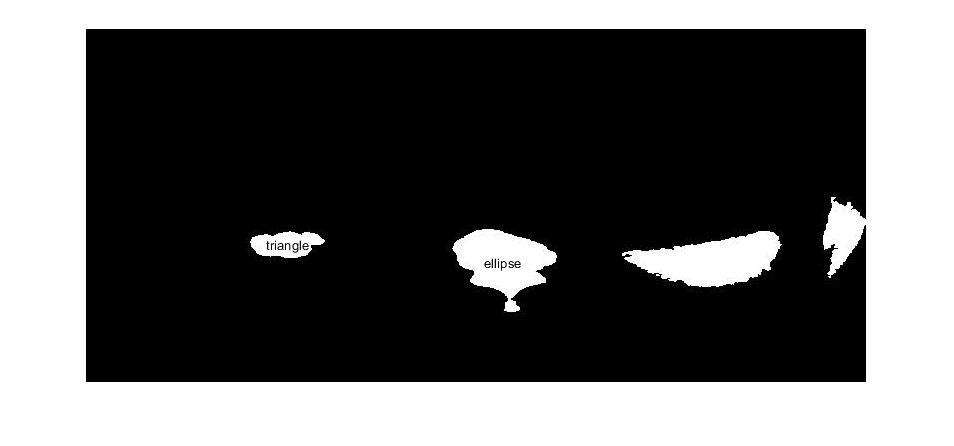

dim =    163     2


khoangcach = 1×1 cell array
    {[35.690003835050533]}


khoangcach = 1×1 cell array
    {1×2 double}


khoangcach = 1×1 cell array
    {1×3 double}


khoangcach = 1×1 cell array
    {1×4 double}


khoangcach = 1×1 cell array
    {1×5 double}


khoangcach = 1×1 cell array
    {1×6 double}


khoangcach = 1×1 cell array
    {1×7 double}


khoangcach = 1×1 cell array
    {1×8 double}


khoangcach = 1×1 cell array
    {1×9 double}


khoangcach = 1×1 cell array
    {1×10 double}


khoangcach = 1×1 cell array
    {1×11 double}


khoangcach = 1×1 cell array
    {1×12 double}


khoangcach = 1×1 cell array
    {1×13 double}


khoangcach = 1×1 cell array
    {1×14 double}


khoangcach = 1×1 cell array
    {1×15 double}


khoangcach = 1×1 cell array
    {1×16 double}


khoangcach = 1×1 cell array
    {1×17 double}


khoangcach = 1×1 cell array
    {1×18 double}


khoangcach = 1×1 cell array
    {1×19 double}


khoangcach = 1×1 cell array
    {1×20 double}


khoangcach = 1×1 cell array
    {1×21 double}


khoangcach = 1×1 cell array
    {1×22 double}


khoangcach = 1×1 cell array
    {1×23 double}


khoangcach = 1×1 cell array
    {1×24 double}


khoangcach = 1×1 cell array
    {1×25 double}


khoangcach = 1×1 cell array
    {1×26 double}


khoangcach = 1×1 cell array
    {1×27 double}


khoangcach = 1×1 cell array
    {1×28 double}


khoangcach = 1×1 cell array
    {1×29 double}


khoangcach = 1×1 cell array
    {1×30 double}


khoangcach = 1×1 cell array
    {1×31 double}


khoangcach = 1×1 cell array
    {1×32 double}


khoangcach = 1×1 cell array
    {1×33 double}


khoangcach = 1×1 cell array
    {1×34 double}


khoangcach = 1×1 cell array
    {1×35 double}


khoangcach = 1×1 cell array
    {1×36 double}


khoangcach = 1×1 cell array
    {1×37 double}


khoangcach = 1×1 cell array
    {1×38 double}


khoangcach = 1×1 cell array
    {1×39 double}


khoangcach = 1×1 cell array
    {1×40 double}


khoangcach = 1×1 cell array
    {1×41 double}


khoangcach = 1×1 cell array
    {1×42 double}


khoangcach = 1×1 cell array
    {1×43 double}


khoangcach = 1×1 cell array
    {1×44 double}


khoangcach = 1×1 cell array
    {1×45 double}


khoangcach = 1×1 cell array
    {1×46 double}


khoangcach = 1×1 cell array
    {1×47 double}


khoangcach = 1×1 cell array
    {1×48 double}


khoangcach = 1×1 cell array
    {1×49 double}


khoangcach = 1×1 cell array
    {1×50 double}


khoangcach = 1×1 cell array
    {1×51 double}


khoangcach = 1×1 cell array
    {1×52 double}


khoangcach = 1×1 cell array
    {1×53 double}


khoangcach = 1×1 cell array
    {1×54 double}


khoangcach = 1×1 cell array
    {1×55 double}


khoangcach = 1×1 cell array
    {1×56 double}


khoangcach = 1×1 cell array
    {1×57 double}


khoangcach = 1×1 cell array
    {1×58 double}


khoangcach = 1×1 cell array
    {1×59 double}


khoangcach = 1×1 cell array
    {1×60 double}


khoangcach = 1×1 cell array
    {1×61 double}


khoangcach = 1×1 cell array
    {1×62 double}


khoangcach = 1×1 cell array
    {1×63 double}


khoangcach = 1×1 cell array
    {1×64 double}


khoangcach = 1×1 cell array
    {1×65 double}


khoangcach = 1×1 cell array
    {1×66 double}


khoangcach = 1×1 cell array
    {1×67 double}


khoangcach = 1×1 cell array
    {1×68 double}


khoangcach = 1×1 cell array
    {1×69 double}


khoangcach = 1×1 cell array
    {1×70 double}


khoangcach = 1×1 cell array
    {1×71 double}


khoangcach = 1×1 cell array
    {1×72 double}


khoangcach = 1×1 cell array
    {1×73 double}


khoangcach = 1×1 cell array
    {1×74 double}


khoangcach = 1×1 cell array
    {1×75 double}


khoangcach = 1×1 cell array
    {1×76 double}


khoangcach = 1×1 cell array
    {1×77 double}


khoangcach = 1×1 cell array
    {1×78 double}


khoangcach = 1×1 cell array
    {1×79 double}


khoangcach = 1×1 cell array
    {1×80 double}


khoangcach = 1×1 cell array
    {1×81 double}


khoangcach = 1×1 cell array
    {1×82 double}


khoangcach = 1×1 cell array
    {1×83 double}


khoangcach = 1×1 cell array
    {1×84 double}


khoangcach = 1×1 cell array
    {1×85 double}


khoangcach = 1×1 cell array
    {1×86 double}


khoangcach = 1×1 cell array
    {1×87 double}


khoangcach = 1×1 cell array
    {1×88 double}


khoangcach = 1×1 cell array
    {1×89 double}


khoangcach = 1×1 cell array
    {1×90 double}


khoangcach = 1×1 cell array
    {1×91 double}


khoangcach = 1×1 cell array
    {1×92 double}


khoangcach = 1×1 cell array
    {1×93 double}


khoangcach = 1×1 cell array
    {1×94 double}


khoangcach = 1×1 cell array
    {1×95 double}


khoangcach = 1×1 cell array
    {1×96 double}


khoangcach = 1×1 cell array
    {1×97 double}


khoangcach = 1×1 cell array
    {1×98 double}


khoangcach = 1×1 cell array
    {1×99 double}


khoangcach = 1×1 cell array
    {1×100 double}


khoangcach = 1×1 cell array
    {1×101 double}


khoangcach = 1×1 cell array
    {1×102 double}


khoangcach = 1×1 cell array
    {1×103 double}


khoangcach = 1×1 cell array
    {1×104 double}


khoangcach = 1×1 cell array
    {1×105 double}


khoangcach = 1×1 cell array
    {1×106 double}


khoangcach = 1×1 cell array
    {1×107 double}


khoangcach = 1×1 cell array
    {1×108 double}


khoangcach = 1×1 cell array
    {1×109 double}


khoangcach = 1×1 cell array
    {1×110 double}


khoangcach = 1×1 cell array
    {1×111 double}


khoangcach = 1×1 cell array
    {1×112 double}


khoangcach = 1×1 cell array
    {1×113 double}


khoangcach = 1×1 cell array
    {1×114 double}


khoangcach = 1×1 cell array
    {1×115 double}


khoangcach = 1×1 cell array
    {1×116 double}


khoangcach = 1×1 cell array
    {1×117 double}


khoangcach = 1×1 cell array
    {1×118 double}


khoangcach = 1×1 cell array
    {1×119 double}


khoangcach = 1×1 cell array
    {1×120 double}


khoangcach = 1×1 cell array
    {1×121 double}


khoangcach = 1×1 cell array
    {1×122 double}


khoangcach = 1×1 cell array
    {1×123 double}


khoangcach = 1×1 cell array
    {1×124 double}


khoangcach = 1×1 cell array
    {1×125 double}


khoangcach = 1×1 cell array
    {1×126 double}


khoangcach = 1×1 cell array
    {1×127 double}


khoangcach = 1×1 cell array
    {1×128 double}


khoangcach = 1×1 cell array
    {1×129 double}


khoangcach = 1×1 cell array
    {1×130 double}


khoangcach = 1×1 cell array
    {1×131 double}


khoangcach = 1×1 cell array
    {1×132 double}


khoangcach = 1×1 cell array
    {1×133 double}


khoangcach = 1×1 cell array
    {1×134 double}


khoangcach = 1×1 cell array
    {1×135 double}


khoangcach = 1×1 cell array
    {1×136 double}


khoangcach = 1×1 cell array
    {1×137 double}


khoangcach = 1×1 cell array
    {1×138 double}


khoangcach = 1×1 cell array
    {1×139 double}


khoangcach = 1×1 cell array
    {1×140 double}


khoangcach = 1×1 cell array
    {1×141 double}


khoangcach = 1×1 cell array
    {1×142 double}


khoangcach = 1×1 cell array
    {1×143 double}


khoangcach = 1×1 cell array
    {1×144 double}


khoangcach = 1×1 cell array
    {1×145 double}


khoangcach = 1×1 cell array
    {1×146 double}


khoangcach = 1×1 cell array
    {1×147 double}


khoangcach = 1×1 cell array
    {1×148 double}


khoangcach = 1×1 cell array
    {1×149 double}


khoangcach = 1×1 cell array
    {1×150 double}


khoangcach = 1×1 cell array
    {1×151 double}


khoangcach = 1×1 cell array
    {1×152 double}


khoangcach = 1×1 cell array
    {1×153 double}


khoangcach = 1×1 cell array
    {1×154 double}


khoangcach = 1×1 cell array
    {1×155 double}


khoangcach = 1×1 cell array
    {1×156 double}


khoangcach = 1×1 cell array
    {1×157 double}


khoangcach = 1×1 cell array
    {1×158 double}


khoangcach = 1×1 cell array
    {1×159 double}


khoangcach = 1×1 cell array
    {1×160 double}


khoangcach = 1×1 cell array
    {1×161 double}


khoangcach = 1×1 cell array
    {1×162 double}


khoangcach = 1×1 cell array
    {1×163 double}


vuong =    2.723881810139442


thoi =    1.582727932945383


dim =    298     2


khoangcach = 1×2 cell array
    {1×163 double}    {[53.053436976814083]}


khoangcach = 1×2 cell array
    {1×163 double}    {1×2 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×3 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×4 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×5 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×6 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×7 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×8 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×9 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×10 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×11 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×12 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×13 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×14 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×15 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×16 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×17 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×18 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×19 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×20 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×21 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×22 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×23 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×24 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×25 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×26 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×27 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×28 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×29 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×30 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×31 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×32 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×33 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×34 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×35 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×36 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×37 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×38 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×39 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×40 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×41 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×42 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×43 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×44 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×45 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×46 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×47 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×48 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×49 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×50 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×51 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×52 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×53 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×54 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×55 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×56 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×57 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×58 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×59 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×60 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×61 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×62 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×63 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×64 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×65 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×66 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×67 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×68 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×69 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×70 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×71 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×72 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×73 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×74 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×75 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×76 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×77 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×78 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×79 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×80 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×81 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×82 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×83 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×84 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×85 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×86 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×87 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×88 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×89 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×90 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×91 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×92 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×93 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×94 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×95 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×96 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×97 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×98 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×99 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×100 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×101 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×102 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×103 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×104 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×105 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×106 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×107 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×108 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×109 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×110 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×111 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×112 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×113 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×114 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×115 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×116 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×117 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×118 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×119 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×120 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×121 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×122 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×123 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×124 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×125 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×126 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×127 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×128 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×129 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×130 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×131 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×132 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×133 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×134 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×135 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×136 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×137 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×138 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×139 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×140 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×141 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×142 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×143 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×144 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×145 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×146 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×147 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×148 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×149 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×150 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×151 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×152 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×153 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×154 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×155 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×156 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×157 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×158 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×159 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×160 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×161 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×162 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×163 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×164 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×165 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×166 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×167 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×168 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×169 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×170 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×171 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×172 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×173 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×174 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×175 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×176 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×177 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×178 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×179 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×180 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×181 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×182 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×183 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×184 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×185 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×186 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×187 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×188 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×189 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×190 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×191 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×192 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×193 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×194 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×195 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×196 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×197 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×198 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×199 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×200 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×201 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×202 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×203 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×204 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×205 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×206 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×207 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×208 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×209 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×210 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×211 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×212 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×213 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×214 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×215 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×216 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×217 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×218 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×219 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×220 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×221 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×222 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×223 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×224 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×225 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×226 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×227 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×228 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×229 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×230 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×231 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×232 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×233 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×234 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×235 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×236 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×237 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×238 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×239 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×240 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×241 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×242 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×243 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×244 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×245 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×246 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×247 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×248 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×249 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×250 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×251 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×252 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×253 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×254 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×255 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×256 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×257 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×258 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×259 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×260 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×261 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×262 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×263 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×264 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×265 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×266 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×267 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×268 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×269 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×270 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×271 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×272 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×273 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×274 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×275 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×276 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×277 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×278 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×279 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×280 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×281 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×282 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×283 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×284 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×285 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×286 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×287 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×288 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×289 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×290 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×291 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×292 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×293 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×294 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×295 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×296 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×297 double}


khoangcach = 1×2 cell array
    {1×163 double}    {1×298 double}


vuong =    1.572294740599562


thoi =    1.399266209023989


dim =    344     2


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {[89.854982610063004]}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×2 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×3 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×4 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×5 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×6 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×7 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×8 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×9 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×10 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×11 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×12 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×13 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×14 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×15 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×16 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×17 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×18 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×19 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×20 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×21 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×22 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×23 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×24 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×25 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×26 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×27 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×28 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×29 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×30 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×31 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×32 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×33 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×34 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×35 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×36 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×37 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×38 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×39 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×40 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×41 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×42 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×43 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×44 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×45 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×46 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×47 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×48 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×49 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×50 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×51 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×52 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×53 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×54 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×55 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×56 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×57 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×58 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×59 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×60 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×61 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×62 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×63 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×64 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×65 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×66 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×67 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×68 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×69 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×70 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×71 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×72 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×73 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×74 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×75 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×76 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×77 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×78 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×79 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×80 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×81 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×82 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×83 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×84 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×85 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×86 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×87 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×88 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×89 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×90 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×91 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×92 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×93 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×94 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×95 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×96 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×97 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×98 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×99 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×100 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×101 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×102 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×103 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×104 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×105 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×106 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×107 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×108 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×109 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×110 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×111 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×112 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×113 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×114 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×115 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×116 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×117 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×118 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×119 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×120 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×121 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×122 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×123 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×124 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×125 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×126 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×127 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×128 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×129 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×130 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×131 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×132 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×133 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×134 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×135 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×136 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×137 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×138 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×139 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×140 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×141 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×142 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×143 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×144 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×145 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×146 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×147 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×148 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×149 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×150 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×151 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×152 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×153 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×154 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×155 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×156 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×157 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×158 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×159 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×160 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×161 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×162 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×163 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×164 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×165 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×166 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×167 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×168 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×169 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×170 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×171 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×172 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×173 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×174 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×175 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×176 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×177 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×178 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×179 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×180 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×181 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×182 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×183 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×184 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×185 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×186 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×187 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×188 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×189 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×190 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×191 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×192 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×193 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×194 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×195 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×196 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×197 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×198 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×199 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×200 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×201 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×202 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×203 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×204 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×205 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×206 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×207 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×208 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×209 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×210 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×211 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×212 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×213 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×214 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×215 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×216 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×217 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×218 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×219 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×220 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×221 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×222 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×223 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×224 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×225 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×226 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×227 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×228 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×229 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×230 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×231 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×232 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×233 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×234 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×235 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×236 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×237 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×238 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×239 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×240 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×241 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×242 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×243 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×244 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×245 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×246 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×247 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×248 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×249 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×250 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×251 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×252 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×253 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×254 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×255 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×256 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×257 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×258 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×259 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×260 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×261 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×262 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×263 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×264 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×265 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×266 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×267 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×268 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×269 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×270 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×271 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×272 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×273 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×274 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×275 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×276 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×277 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×278 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×279 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×280 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×281 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×282 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×283 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×284 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×285 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×286 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×287 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×288 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×289 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×290 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×291 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×292 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×293 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×294 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×295 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×296 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×297 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×298 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×299 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×300 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×301 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×302 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×303 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×304 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×305 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×306 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×307 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×308 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×309 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×310 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×311 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×312 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×313 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×314 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×315 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×316 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×317 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×318 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×319 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×320 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×321 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×322 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×323 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×324 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×325 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×326 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×327 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×328 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×329 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×330 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×331 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×332 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×333 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×334 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×335 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×336 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×337 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×338 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×339 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×340 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×341 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×342 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×343 double}


khoangcach = 1×3 cell array
    {1×163 double}    {1×298 double}    {1×344 double}


vuong =    4.252176611091302


thoi =    1.681245743252651


dim =    352     2


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {[15.473575227007911]}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×2 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×3 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×4 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×5 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×6 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×7 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×8 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×9 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×10 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×11 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×12 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×13 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×14 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×15 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×16 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×17 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×18 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×19 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×20 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×21 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×22 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×23 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×24 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×25 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×26 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×27 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×28 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×29 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×30 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×31 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×32 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×33 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×34 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×35 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×36 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×37 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×38 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×39 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×40 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×41 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×42 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×43 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×44 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×45 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×46 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×47 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×48 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×49 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×50 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×51 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×52 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×53 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×54 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×55 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×56 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×57 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×58 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×59 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×60 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×61 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×62 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×63 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×64 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×65 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×66 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×67 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×68 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×69 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×70 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×71 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×72 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×73 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×74 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×75 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×76 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×77 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×78 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×79 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×80 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×81 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×82 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×83 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×84 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×85 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×86 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×87 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×88 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×89 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×90 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×91 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×92 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×93 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×94 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×95 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×96 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×97 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×98 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×99 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×100 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×101 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×102 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×103 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×104 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×105 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×106 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×107 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×108 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×109 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×110 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×111 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×112 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×113 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×114 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×115 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×116 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×117 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×118 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×119 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×120 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×121 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×122 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×123 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×124 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×125 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×126 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×127 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×128 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×129 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×130 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×131 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×132 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×133 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×134 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×135 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×136 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×137 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×138 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×139 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×140 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×141 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×142 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×143 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×144 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×145 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×146 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×147 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×148 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×149 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×150 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×151 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×152 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×153 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×154 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×155 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×156 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×157 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×158 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×159 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×160 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×161 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×162 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×163 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×164 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×165 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×166 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×167 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×168 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×169 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×170 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×171 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×172 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×173 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×174 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×175 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×176 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×177 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×178 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×179 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×180 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×181 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×182 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×183 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×184 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×185 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×186 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×187 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×188 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×189 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×190 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×191 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×192 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×193 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×194 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×195 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×196 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×197 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×198 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×199 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×200 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×201 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×202 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×203 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×204 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×205 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×206 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×207 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×208 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×209 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×210 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×211 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×212 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×213 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×214 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×215 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×216 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×217 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×218 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×219 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×220 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×221 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×222 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×223 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×224 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×225 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×226 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×227 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×228 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×229 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×230 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×231 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×232 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×233 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×234 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×235 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×236 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×237 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×238 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×239 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×240 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×241 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×242 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×243 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×244 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×245 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×246 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×247 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×248 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×249 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×250 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×251 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×252 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×253 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×254 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×255 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×256 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×257 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×258 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×259 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×260 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×261 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×262 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×263 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×264 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×265 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×266 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×267 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×268 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×269 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×270 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×271 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×272 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×273 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×274 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×275 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×276 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×277 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×278 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×279 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×280 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×281 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×282 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×283 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×284 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×285 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×286 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×287 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×288 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×289 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×290 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×291 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×292 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×293 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×294 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×295 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×296 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×297 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×298 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×299 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×300 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×301 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×302 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×303 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×304 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×305 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×306 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×307 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×308 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×309 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×310 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×311 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×312 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×313 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×314 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×315 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×316 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×317 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×318 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×319 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×320 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×321 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×322 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×323 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×324 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×325 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×326 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×327 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×328 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×329 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×330 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×331 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×332 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×333 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×334 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×335 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×336 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×337 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×338 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×339 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×340 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×341 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×342 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×343 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×344 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×345 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×346 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×347 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×348 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×349 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×350 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×351 double}


khoangcach = 1×4 cell array
    {1×163 double}    {1×298 double}    {1×344 double}    {1×352 double}


vuong =    0.657373573596536


thoi =    0.306857783682158


figure;imshow(i);
hold on;
for k=1:dim(1)
    b= boundaries{k};
    dim = size(b)
    for i=1:dim(1)
        khoangcach{k}(1,i) = sqrt ( ( b(i,2) - s(k).Centroid(1) )^2 + ( b(i,1) - s(k).Centroid(2) )^2 )
    end 
    a=max(khoangcach{k});
    b=min(khoangcach{k});
    c=dt(k).Area;
    dolech=a-b;
    vuong = c/(4*b^2)
    chunhat=c/(4*b*(a^2-b^2)^0.5);
    tamgiacdeu=(c*3^0.5)/((a+b)^2);
    elip =c/(a*b*pi);
    thoi= (c*( a^2 - b^2 )^0.5) / (2*a^2*b)
    if dolech < 10
            text(s(k).Centroid(1)-20,s(k).Centroid(2),'circle')
    elseif (vuong < 1.05 ) && (vuong > 0.95 )
            text(s(k).Centroid(1)-20,s(k).Centroid(2),'square')
    elseif (elip < 1.05 ) && (elip > 0.95 )
            text(s(k).Centroid(1)-20,s(k).Centroid(2),'ellipse')
    elseif (thoi < 1.05 ) && (thoi > 0.95 )
            text(s(k).Centroid(1)-20,s(k).Centroid(2),'diamond')
    elseif ((chunhat <1.05) && (chunhat >0.95))
            text(s(k).Centroid(1)-20,s(k).Centroid(2),'rectangle')
    elseif  (tamgiacdeu < 1.05 ) && (tamgiacdeu > 0.95 )
            text(s(k).Centroid(1)-20,s(k).Centroid(2),'triangle')
    end
end